Reflection Coefficent (Gamma)

clear;


Smithchart

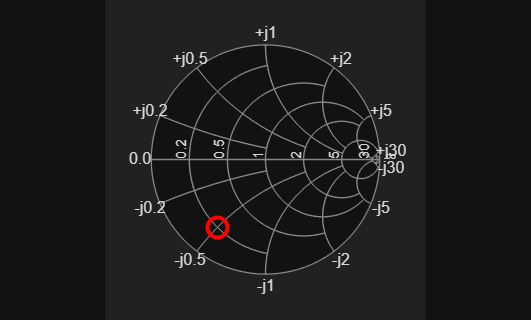

clear;
% SmithchartPlot(input,Gamma,Z0,ZL)
% EX 1
ZL = 15 - 37.5*1j;
Z0 = 75;
%SmithchartPlot('Load',[],Z0,ZL);

Trignomial (cos/sin) --> phasor amplitude (only for uniform waves)

clear;
% E0 = E2Phasor(Ex_cos,Ey_cos,Ez_cos,Ex_sin,Ey_sin,Ez_sin);
% E = [x,y,z]*cos = Ex_cos, Ey_cos, Ez_cos
% E = [x,y,z]*sin = Ex_sin, Ey_sin, Ez_sin

% EX 1 
Ex_cos = 5; Ey_cos = 0; Ez_cos = 0;
Ex_sin = 0; Ey_sin = 0; Ez_sin = -15;
E0 = E2Phasor(Ex_cos,Ey_cos,Ez_cos,Ex_sin,Ey_sin,Ez_sin);
E0

E0 =    5.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 +15.0000i


(E) Electric field --> (H) Magnetic field

clear;
% H = E2H(E,beta,medium); 
% EX 1
E = [5,0,1j*15];
beta = [0, -10, 0];

medium.eta = 377;

H = E2H(E,beta,medium); 
H

H =    0.0000 - 0.0398i
   0.0000 + 0.0000i
   0.0133 + 0.0000i



clear;
% EX 2
E0 = 10;
E = E0*([2,1,0] - [0,-1*1j,-2*1j]); % remember if sin: -1j
beta = [2,-4,2];

medium.eta = 377;

H = E2H(E,beta,medium);
H

H =   -0.0108 - 0.0541i
   0.0217 - 0.0217i
   0.0541 + 0.0108i


Intrinsic polarization (AR, handedness)

clear;
% pol = Polarization(E0, beta)
% EX 1
H = [0, 10+1j*10, 10-1j*10];
beta = [1, 0, 0];

pol = Polarization(H,beta);
pol.AR

ans = 1.0000

pol.hand

ans = 'RH'

pol.type

ans = 'circular'


clear;
% EX 2
beta0 = 20.94;
beta = beta0*[sqrt(3)/2,-1/2,0];
E0 = 5;
E = E0*[1, sqrt(3),1j*2];

pol = Polarization(E,beta);
pol.AR

ans = 1.0000

pol.hand

ans = 'LH'

pol.type

ans = 'circular'

Type of incidence

clear;
% result = IncidenceType(E, beta, surface)
% EX 1

beta0 = 20.94;
beta = beta0*[sqrt(3)/2,-1/2,0];
E0 = 5;
E = E0*[1, sqrt(3),1j*2];

result = IncidenceType(E,beta,'yz');
result.type

ans = "Mixed"

result.description

ans = "Oblique incidence with both TE and TM components"


clear;
% EX 2
E = [1+1j, 0, 0];
beta = [0,20,-30];

result = IncidenceType(E,beta,'xz');
result.type

ans = "TE"

result.description

ans = "Oblique transverse electric incidence (E ⟂ plane of incidence)"

Angle of transmission and angle of incidence

clear;
% [theta_i, theta_t, tir] = WaveAngle(beta, eps_r1, eps_r2, plane)
% In air: eps_r1 = 1
% EX 1
beta   = [0, 20, -30];
eps_r1 = 1;
eps_r2 = 12;

[theta_i, theta_t, tir] = WaveAngle(beta, eps_r1, eps_r2, 'xz');

theta_i

theta_i = 56.3099

theta_t

theta_t = 13.8979

tir

tir = logical
   0



clear;
% EX 2
eps_r1 = 1; % in air
eps_r2 = 4;
beta0 = 20.94;
beta = beta0*[sqrt(3)/2, -1/2, 0];

[theta_i, theta_t, tir] = WaveAngle(beta,eps_r1,eps_r2,'yz');
theta_i

theta_i = 30.0000

theta_t

theta_t = 14.4775

tir

tir = logical
   0


Power and time averaging poynting vectors (S)

clear;
% power = WavePower(E0, beta, medium, n_hat, A)
% Time averaging poynting vector
% EX 1
E0 = 10;
E = E0*([2, 1, 0] -1j*[0, -1, -2]);
beta = [2, -4, 2];
medium.eta = 377; % in air

power = WavePower(E,beta,medium,[],[]);
power.Savg % Time averaging poynting vector (W/m^2)

ans =     0.5414
   -1.0829
    0.5414


power.H0   % Magnetic phasor amplitude (A/m)

ans =   -0.0108 - 0.0541i
   0.0217 - 0.0217i
   0.0541 + 0.0108i



% EX 2
n_hat = 1/sqrt(2)*[1, 0, 1];
d = 1; % circle diamater
A = pi*(d/2)^2; % circle = pi*r^2

power = WavePower(E,beta,medium,n_hat,A);
power.P % Incidence power (W)

ans = 0.6014

Amount of incidnce power reflected / transmitted 

clear;
% result = PowerFraction(kind, pol, Ephasor, k_hat, n_hat,
%                             eps_r1, mu_r1, eps_r2, mu_r2)
% EX 1
eps_r1 = 1; mu_r1 = 1; mu_r2 = 1; % In air: 
eps_r2 = 4; 
E0 = 5;
E = E0*[1, sqrt(3), 1j*2];
beta0 = 20.94;
beta = beta0*[sqrt(3)/2, -1/2, 0];

% Find 'pol' ('TM', 'TE', 'mixed')
result1 = IncidenceType(E, beta, 'yz');
result1.type

ans = "Mixed"


n_hat = [1,0,0]; % surface normal 'yz' = [1,0,0]

result = PowerFraction('reflected','mixed',E,beta,n_hat,eps_r1,mu_r1,eps_r2,mu_r2);
result.R_TE

ans = 0.1459

result.R_TM

ans = 0.0800


% Remember if mixed incidence type, use (TE + TM)*/2
R_mixed = (result.R_TE + result.R_TM)*100/2

R_mixed = 11.2954

Solenoid

clear;
% sol = Solenoid(mu_r, N, A, ell, varargin)
% EX 1
mu_r1 = 1; % in air
N = 200;
l = 10e-2;
d = 1.3e-2; % diamater not area
A = pi*(d/2)^2;
B = 6.28e-3;

sol = Solenoid(mu_r1,N,A,l,'B',B);
sol.I % current through windings (A)

ans = 2.4987

sol.L % self inductance (H)

ans = 6.6719e-05


clear;
% EX 2
mu_r1 = 1; % in air
l = 8e-2;
d = 1e-2;
A = pi*(d/2)^2;
I = 2;
B = 10e-3;
N = 1000/pi;

sol = Solenoid(mu_r1,N,A,l,'I',I);
sol.B % Has to match our B

ans = 0.0100

sol.L

ans = 1.2500e-04

Capacitor

clear;
% cap = Capacitor('parallel', eps_r, A, d, 'V', V)
% cap = Capacitor('coax',     eps_r, a, b, l, 'Q', Q)
% cap = Capacitor('twowire',  eps_r, r, D, l, 'V', V)
% EX 1
eps_r = 4.2;
a1 = 1e-2; a = a1/2;
b1 = 5e-2; b = b1/2;
l = 10e-2;
V = 12;

cap = Capacitor('coax',eps_r,a,b,l,'V',V);
cap.C % capacitance (F)

ans = 1.4518e-11

cap.W % electrostatic energy stored (J)

ans = 1.0453e-09


clear;
% EX 2
eps_r = 1;
R     = 1e-3;   % radius (m)
d     = 5e-3;   % center spacing (m)
l     = 2;      % length (m)

cap = Capacitor('twowire', eps_r, R, d, l);
cap.C % capacitance (F)

ans = 3.5507e-11